# Calcualtion of Inter Hamming Distance for all devices with AuNPs

 (C) 2021, Juan Esteban Villegas, NYUAD

For this test, we compare all combinations of the response of the same device type and compute all HD metrics for each design. We then generate plots of  Hamming Distance combining all resulting HDs.

## Read data

First extract the data from the H5 file. 

clear('files', 'interAu1_dev1', 'interAu1_dev2', 'interAu1_dev3');
folder = '..\Datasets\';

files{1} = 'AllDevices_Au1_Chips02_02_TM_user01_1705.h5';
files{2} = 'AllDevices_Au1_Chips02_02_TM_user02_1705.h5';

idx = 1;
for file = files
    filename = strcat(folder,file{1});
    struct = h52struct(filename);
    data{idx} = struct.project.measurements; 
    idx = idx+1;
end

%Data is tagged using var(1) as the device index and var(2) as the port
%index. We compare only the drop ports in the design 3 type of devices.
dev_ind   = 13:24;    % Index of the devices of interest()  
dev_port = ones(1,length(dev_ind)); dev_port(9:12) = 1;

ind_file = 1; clear dataset;
for file = files
    meas = data{ind_file} ;
    response=[];
    for i = 1:length(dev_ind)
        idx = findinproject(dev_ind(i),dev_port(i),meas);
        extract_meas = meas(idx); 
        if (iscell(extract_meas)), extract_meas = extract_meas{1};end
        m = extract_meas.spectra;
        response(:,i) = m(:,2);
        lambda = m(:,1);
    end
    dataset{ind_file} = response;
    ind_file = ind_file+1;
end

We now compute  the HD metrics for each file, the shifted datasets are computed inside of the function MultiHD. We test all possible combinations of pairs of measurements of the same device to compute the average Hamming Distance for each device. We have a total of 4 devices being tested with and without shifting the spectrum to accomodate for possible small spectral misalignements. We  have a total of N choose 2 pairwise  comparisons per device (6).

L=0.15; clear('interAu1_dev1','interAu1_dev2','interAu1_dev3','avg','sigma')
for it = 1:length(files)
    interAu1_dev1{it} = multi_HD(lambda, dataset{it}(:,1:4 ), L);
    interAu1_dev2{it} = multi_HD(lambda, dataset{it}(:,5:8 ), L);
    interAu1_dev3{it} = multi_HD(lambda, dataset{it}(:,9:12), L);
    
    %% TE distance metrics
    avg{it} = [ mean(interAu1_dev1{it}.mean{1}); ...
                mean(interAu1_dev2{it}.mean{1}); ...
                mean(interAu1_dev3{it}.mean{1})];
    
    sigma{it} = [ mean(interAu1_dev1{it}.mean{2}); ...
                  mean(interAu1_dev2{it}.mean{2}); ...
                  mean(interAu1_dev3{it}.mean{2})];
end

559.5± 33.1 (559.1± 33.2) 	542.2± 35.2 (524.7± 34.8) 	583.7± 29.3 (566.3± 28.3) 	 
0.422± 0.041 (0.424± 0.040) 	0.392± 0.039 (0.381± 0.039) 	0.494± 0.039 (0.485± 0.039) 	 
0.420± 0.042 (0.418± 0.042) 	0.432± 0.043 (0.423± 0.043) 	0.475± 0.041 (0.476± 0.041) 	 
 
596.4± 34.9 (595.4± 34.3) 	591.2± 37.0 (571.5± 36.2) 	584.7± 29.7 (558.1± 26.6) 	 
0.463± 0.041 (0.462± 0.041) 	0.436± 0.040 (0.427± 0.040) 	0.521± 0.037 (0.521± 0.037) 	 
0.461± 0.041 (0.457± 0.041) 	0.451± 0.044 (0.446± 0.043) 	0.527± 0.041 (0.534± 0.040) 	 
 



all_avg = (avg{1}+avg{2})/2 ;
all_sigma = (sigma{1}+sigma{2})/2 ;
display_results(all_avg, all_sigma);

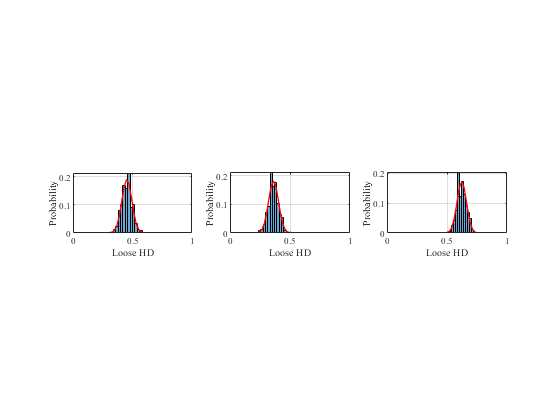

%Plot of LHD
 for file = files
    h = figure(); clf, hold off; haxis = [0,1]; 
    metric =3; device = 1; %Loose HD
    subplot(1,3,1), 
    h = plotHD(interAu1_dev1{it}.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;
    subplot(1,3,2), 
    h = plotHD(interAu1_dev2{it}.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;
    subplot(1,3,3),
    h = plotHD(interAu1_dev3{it}.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;      
 end